# Detect Facial Expression using Fisher Linear Discriminant, PCA, Bayes Decision Theory and K-NN

## Loading data.mat dataset

faces = load('data.mat');

Each image is 21x24 pixel, 200 images each for neutral, smiling and illuminated expressions. The illuminated images are supposedly all neutral faces and will be used as our testing set.

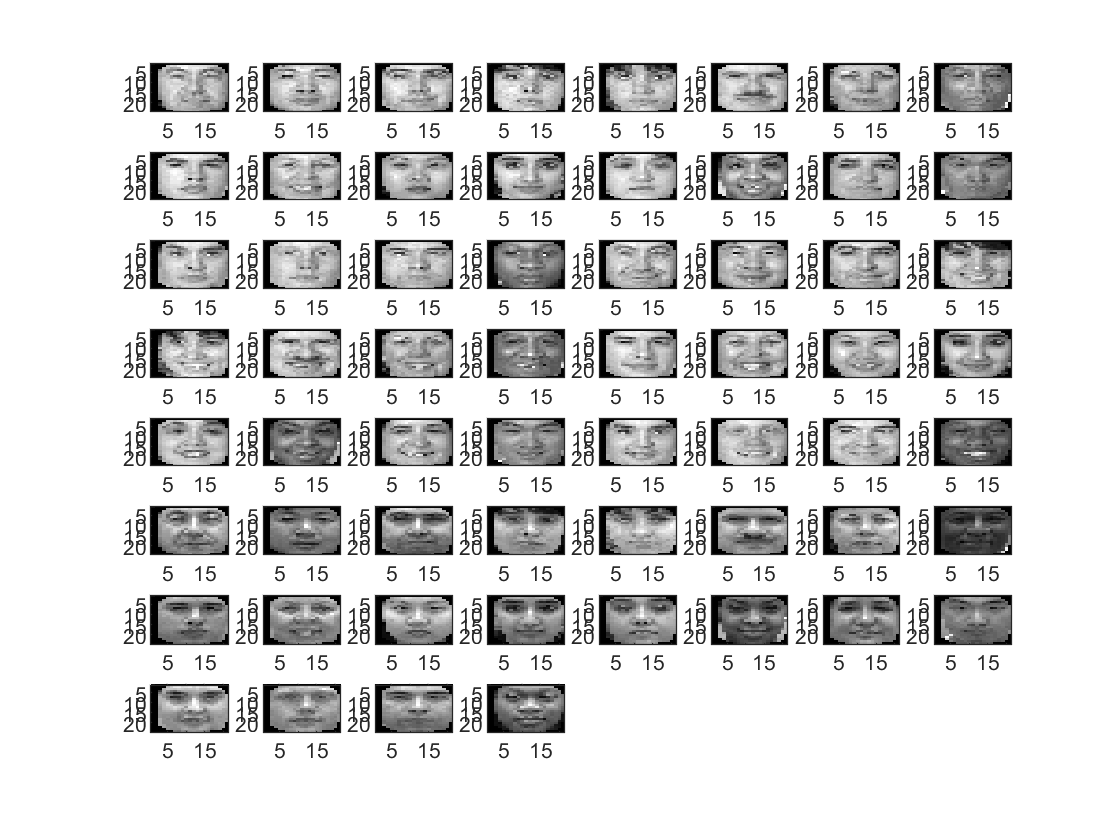

[fn, fs, fi] = deal(faces.face(:,:,1:3:end), faces.face(:,:,2:3:end),faces.face(:,:,3:3:end));
figure, clf;
colormap 'gray';
for i=1:20 %Displaying 20 images of each class
    subplot(8,8,i);
    imagesc(fn(:,:,i)); 
    subplot(8,8,i+20);
    imagesc(fs(:,:,i));
    subplot(8,8,i+40);
    imagesc(fi(:,:,i));
end

## Fisher Discriminant Analysis

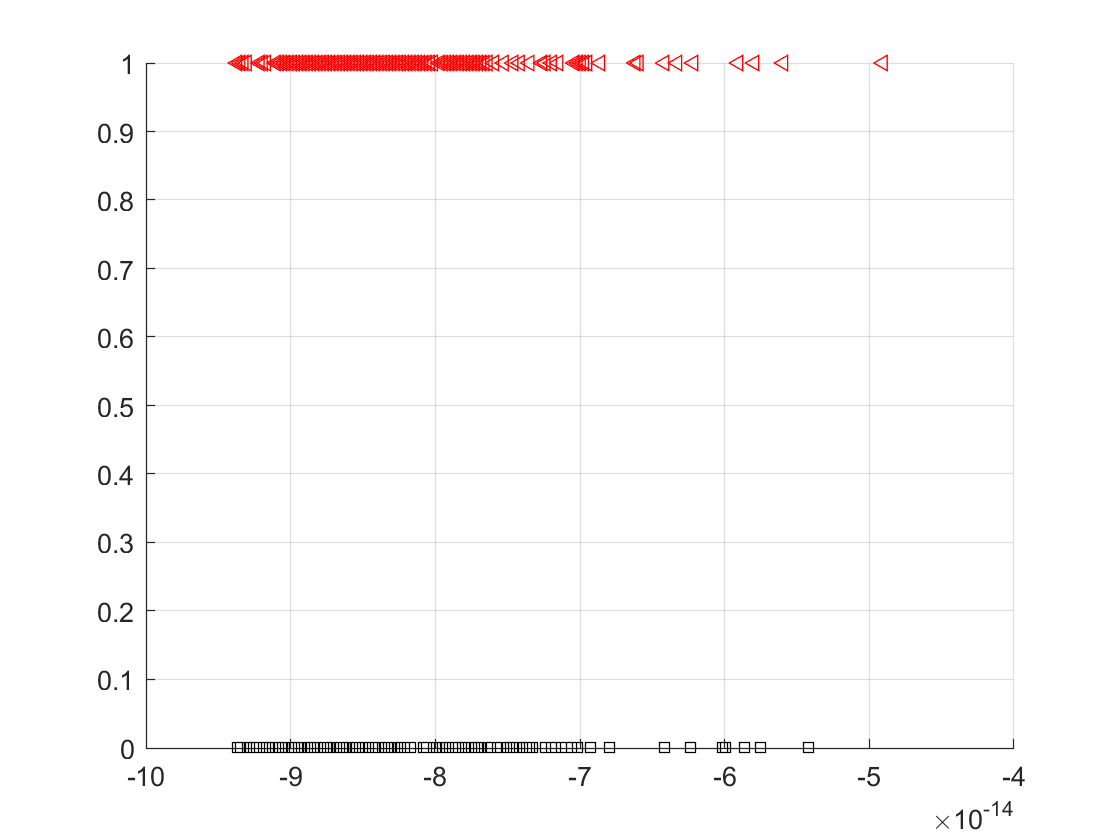

tst_trn_spl = 1.0; %Using entire set of neutral and smiling faces for training
[d1, d2, n] = deal(size(fn,1), size(fn,2), size(fn,3)*tst_trn_spl);
[X1 X2] = deal(zeros(n,d1*d2));
for i=1:n
    tmp1=fn(:,:,i); tmp2=fs(:,:,i);
    X1(i,:)=tmp1(:)'; X2(i,:)=tmp2(:)'; 
end
mn = mean(X1,1); ms=mean(X2,1);
Xc1 = X1-ones(n,1)*mn; Xc2=X2-ones(n,1)*ms; %Centering the data about the class mean
S1 = Xc1'*Xc1; S2=Xc2'*Xc2; %Determine the scatter matrix for each class
Sw = S1 + S2; %Building the within class scatter matrix
Sb = (mn - ms)'*(mn - ms); %Building the between class scatter matrix
[W, lam0] = eig(Sb,Sw);
lam0 = sort(lam0,'descend'); [lams, idx] = sort(lam0,2,'descend');
Ws = W(:,idx);
w = Ws(:,1); %Taking the eigenvator corresponding to the highest Eigenvalue
X = [X1;X2];
D1= 1:n; D2=n+1:2*n;
y=X*w;
figure; hold on; grid;
plot(y(D1),zeros(n,1),'s','color','none','MarkerEdgeColor','k','MarkerSize',5);
plot(y(D2),ones(n,1),'<','color','none','MarkerEdgeColor','r','MarkerSize',5);

Plotting the data in one dimension to visually inspect for variability. Although the data is sufficiently variable in this 1-D using FDA, they are not separable as their mean and variance alsmost coincide

## Attempt to map the data with reduced dimension using PCA

[U, Sigma, V] = svd(X','econ');

Projecting to 18 dimensions. Ran experiements with several values of nPCA and 18 looks liek the optimal value

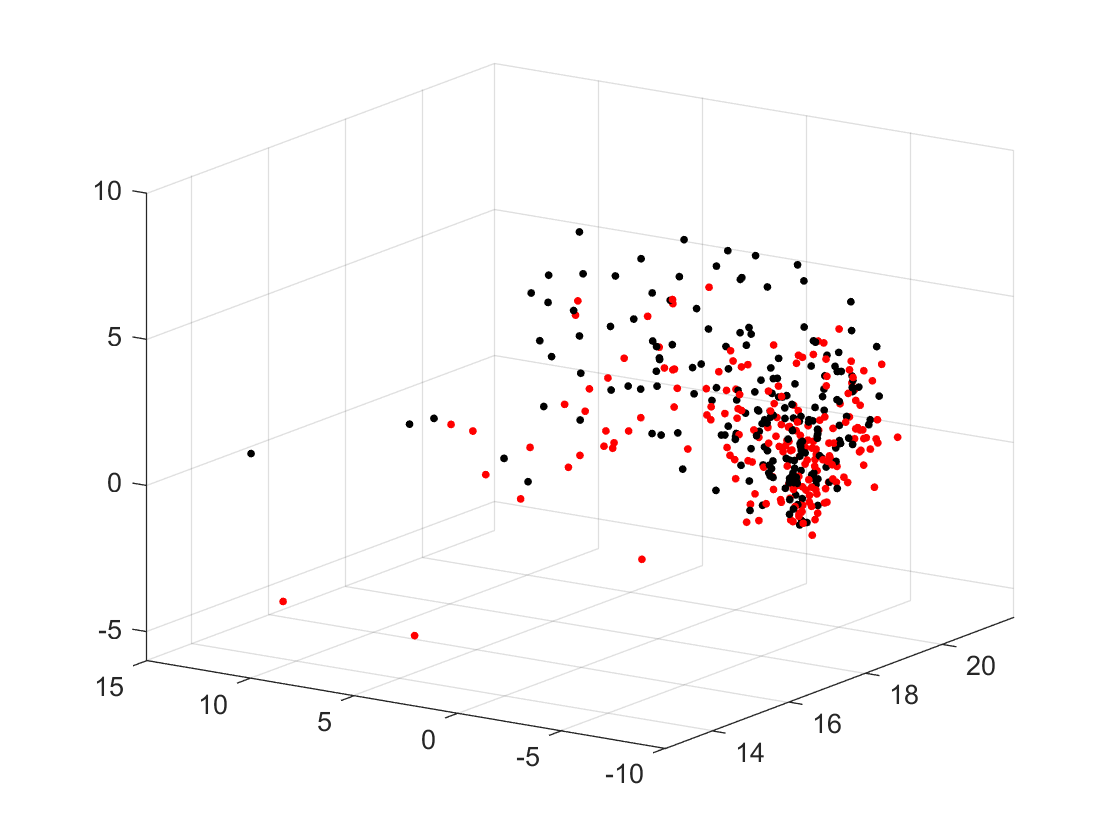

nPCA = 18; 
Yb = X*U(:,1:nPCA); %Mapped the training data to 18 dimensions from 504
figure; hold on; grid;
plot3(Yb(D1,1),Yb(D1,2),Yb(D1,3),'.r', Yb(D2,1),Yb(D2,2),Yb(D2,3),'.k',...
'MarkerSize',10);
view([-56.2 18.5])

From above 3-D plot, visually it appears to be well separated. Hence we'll apply Bayes Discriminant function of the mapped data

## Use Bayesian Classifier

Yb1 = Yb(D1,:); Yb2 = Yb(D2,:);
mb1 = mean(Yb1); mb2 = mean(Yb2);
norm(mb1 - mb2)

ans = 3.2136

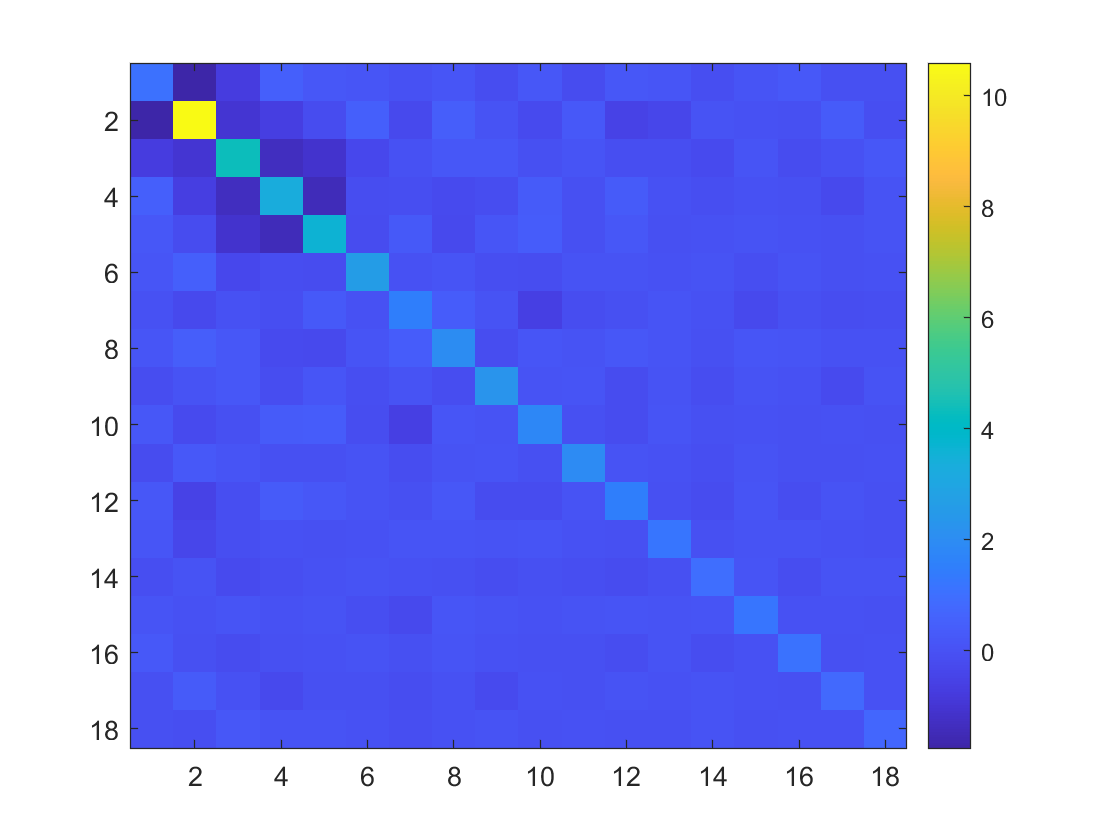

Yb1c = Yb1 - ones(n,1)*mb1; %Centering the data in the PCA reduced dimension
Yb2c = Yb2 - ones(n,1)*mb2;
Sb1 = Yb1c'*Yb1c/(n-1); %Build Covariance matrix for each class
Sb2 = Yb2c'*Yb2c/(n-1);
figure; imagesc(Sb1);colorbar;

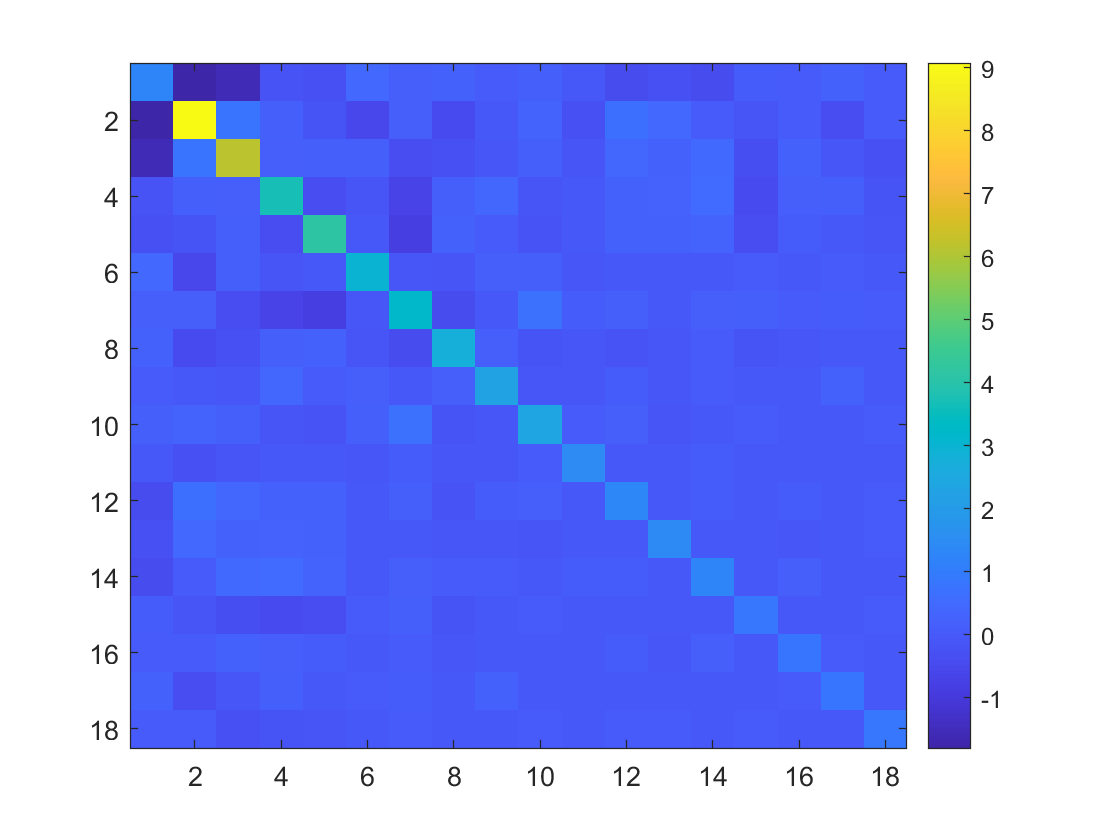

figure;imagesc(Sb2);colorbar;

The distance between the class means (3.2136) are well separated and the variance (~10) is such that the overlap is minimal is 1-D. It'll be further less in 18-D.

% Define the Bayes discriminant functions
iSb1 = inv(Sb1); iSb2 = inv(Sb2);
Sb1d = det(Sb1); Sb2d = det(Sb2);
f1 = @(x)((2*pi)^(-nPCA/0.5))*(1/(Sb1d^0.5))*exp((-0.5)*(x-mb1')'*iSb1*(x-mb1'));
f2 = @(x)((2*pi)^(-nPCA/0.5))*(1/(Sb2d^0.5))*exp((-0.5)*(x-mb2')'*iSb2*(x-mb2'));
label = zeros(size(fn,3)*0.3,1);

Running the test on the illuminated faces that are all supposed to be neutral.

for i=1:size(fi,3)
    tmp1=fi(:,:,i);
    xt = tmp1(:)'*U(:,1:nPCA);
    p1 = f1(xt'); 
    p2 = f2(xt');
    if p1 < p2
        label(i) = 2;
    else
        label(i) = 1;
    end
end
fn_predict = find(label == 1);
fs_predict = find(label == 2);
fprintf('Testing Illuminated faces: positive=%d, negative=%d, Error=%f\n',...
    size(fn_predict,1), size(fs_predict,1),size(fs_predict,1)/(size(fn_predict,1)+size(fs_predict,1)));

Testing Illuminated faces: positive=187, negative=13, Error=0.065000


The Bayes classifier worked pretty well in predicting the the neutral faces with 93.5% accuracy

## Run K-NN classifier with Euclidean distance metric

for NN = 1:100 %Nearest Neighbor parameter
    dist = zeros(400,1);
    for i=1:size(fi,3)
        tmp1=fi(:,:,i);
        xt = tmp1(:)'*U(:,1:nPCA);
        for j=1:(size(fn,3) + size(fs,3))
            % Calculate the distance from each of the 400 training points
            dist(j) = (sum((xt - Yb(j,:)).^2))^(0.5);
        end
        [dist_s, i_dist] = sort(dist,"ascend"); %Sorting them to take the 1st NN neighbors
        % The index position > 200 indicates the neighbor belongs to class 2
        if sum(i_dist(1:NN,1) > size(fn,3)) > NN/2
            label(i) = 2;
        else
            label(i) = 1;
        end
    end
    fn_predict = find(label == 1);
    fs_predict = find(label == 2);
    fprintf('Testing Illuminated faces for %d NN: positive=%d, negative=%d, Error=%f\n',...
        NN, size(fn_predict,1), size(fs_predict,1),size(fs_predict,1)/(size(fn_predict,1)+size(fs_predict,1)));
end

Testing Illuminated faces for 1 NN: positive=160, negative=40, Error=0.200000
Testing Illuminated faces for 2 NN: positive=194, negative=6, Error=0.030000
Testing Illuminated faces for 3 NN: positive=170, negative=30, Error=0.150000
Testing Illuminated faces for 4 NN: positive=184, negative=16, Error=0.080000
Testing Illuminated faces for 5 NN: positive=173, negative=27, Error=0.135000
Testing Illuminated faces for 6 NN: positive=182, negative=18, Error=0.090000
Testing Illuminated faces for 7 NN: positive=174, negative=26, Error=0.130000
Testing Illuminated faces for 8 NN: positive=182, negative=18, Error=0.090000
Testing Illuminated faces for 9 NN: positive=170, negative=30, Error=0.150000
Testing Illuminated faces for 10 NN: positive=181, negative=19, Error=0.095000
Testing Illuminated faces for 11 NN: positive=174, negative=26, Error=0.130000
Testing Illuminated faces for 12 NN: positive=179, negative=21, Error=0.105000
Testing Illuminated faces for 13 NN: positive=176, negative=24

The best classification is obtained with 4 nearest neighbors with 92% accuracy.